# Sparse Flux Balance Analysis 

## Author: Ronan Fleming, Hoai Minh Le, Systems Biochemistry Group, University of Luxembourg.

## Reviewer: Stefania Magnusdottir, Molecular Systems Physiology Group, University of Luxembourg.

## INTRODUCTION

We consider a biochemical network of  m  molecular species and  n  biochemical reactions. The biochemical network is mathematically represented by a stoichiometric matrix $S\in\mathcal{Z}^{m\times n}$. In standard notation, flux balance analysis (FBA) is the linear optimisation problem


$$\begin{array}{ll}
\min\limits _{v} & \rho(v)\equiv c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $$c\in\Re^{n}$$ is a parameter vector that linearly combines one or more reaction fluxes to form what is termed the objective function,  and where a $$b_{i}<0$$, or  $$b_{i}>0$$, represents some fixed output, or input, of the ith molecular species. A typical application of flux balance analysis is to predict an optimal non-equilibrium steady-state flux vector that optimises a linear objective function, such biomass production rate, subject to bounds on certain reaction rates. Herein we use sparse flux balance analysis to predict a minimal number of active reactions [1], consistent with an optimal objective derived from the result of a standard flux balance analysis problem. In this context *sparse flux balance analysis *requires a solution to the following problem


$$\begin{array}{ll}
\min\limits _{v} & \Vert v\Vert_{0}\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u\\
 & c^{T}v=\rho^{\star}
\end{array}$$


where the last constraint is represents the requirement to satisfy an optimal objective value $\rho^{\star}$  derived from any solution to a flux balance analysis (FBA) problem.

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

If necessary, initialize The Cobra Toolbox using the `initCobraToolbox` function.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

## COBRA model. 

In this tutorial, the model used is the generic reconstruction of human metabolism, the Recon 2.04 [2], which is provided in the COBRA Toolbox. The Recon 2.04 model can also be downloaded from the [Virtual Metabolic Human](https://vmh.uni.lu/#downloadview) webpage. Before proceeding with the simulations, the path for the model needs to be set up:      

global CBTDIR            
load([CBTDIR filesep 'test' filesep 'models' filesep 'Recon2.v04.mat']);            
model = modelR204;            
clear modelR204;

Recon 2.04 is written in the "old style" COBRA format, and we thus use the function `convertOldStyleModel` to convert it to the new COBRA Toolbox format.

model = convertOldStyleModel(model);

## PROCEDURE

Set the tolerance to distinguish between zero and non-zero flux, based on the numerical tolerance of the currently installed optimisation solver.

feasTol = getCobraSolverParams('LP', 'feasTol');

Display the constraints

minInf = -1000;
maxInf = 1000;
printConstraints(model, minInf, maxInf);

MinConstraints:
DM_T_antigen_g_	-1
EX_10fthf(e)	-1
EX_10fthf5glu(e)	-1
EX_10fthf6glu(e)	-1
EX_10fthf7glu(e)	-1
EX_11_cis_retfa(e)	-1
EX_13_cis_retnglc(e)	-1
EX_1glyc_hs(e)	-1
EX_1mncam(e)	-1
EX_2425dhvitd2(e)	-1
EX_2425dhvitd3(e)	-1
EX_24nph(e)	-1
EX_25hvitd2(e)	-1
EX_25hvitd3(e)	-1
EX_2hb(e)	-1
EX_2mcit(e)	-1
EX_34dhoxpeg(e)	-1
EX_34dhphe(e)	-1
EX_35cgmp(e)	-1
EX_3aib(e)	-1
EX_3aib_D(e)	-1
EX_3mlda(e)	-1
EX_4abut(e)	-1
EX_4hdebrisoquine(e)	-1
EX_4hphac(e)	-1
EX_4mptnl(e)	-1
EX_4mtolbutamide(e)	-1
EX_4nph(e)	-1
EX_4nphsf(e)	-1
EX_4pyrdx(e)	-1
EX_5adtststerone(e)	-1
EX_5adtststeroneglc(e)	-1
EX_5adtststerones(e)	-1
EX_5dhf(e)	-1
EX_5fthf(e)	-1
EX_5homeprazole(e)	-1
EX_5htrp(e)	-1
EX_5thf(e)	-1
EX_6dhf(e)	-1
EX_6htststerone(e)	-1
EX_6thf(e)	-1
EX_7dhf(e)	-1
EX_7thf(e)	-1
EX_9_cis_retfa(e)	-1
EX_abt(e)	-1
EX_ac(e)	-1
EX_acac(e)	-1
EX_acald(e)	-1
EX_acetone(e)	-1
EX_acgalfucgalacgalfuc12gal14acglcgalgluside_hs(e)	-1
EX_acgalfucgalacgalfucgalacglcgal14acglcgalgluside_hs(e)	-1
EX_acgam(e)	-1

Select the biomass reaction to optimise

model.biomassBool = strcmp(model.rxns, 'biomass_reaction');
model.c(model.biomassBool) = 1;

Display the biomass reaction

rxnAbbrList={'biomass_reaction'};
printFlag = 1;
formulas = printRxnFormula(model, rxnAbbrList, printFlag);        

biomass_reaction	20.6508 h2o[c] + 20.7045 atp[c] + 0.385872 glu_L[c] + 0.352607 asp_L[c] + 0.036117 gtp[c] + 0.279425 asn_L[c] + 0.505626 ala_L[c] + 0.046571 cys_L[c] + 0.325996 gln_L[c] + 0.538891 gly[c] + 0.392525 ser_L[c] + 0.31269 thr_L[c] + 0.592114 lys_L[c] + 0.35926 arg_L[c] + 0.153018 met_L[c] + 0.023315 pail_hs[c] + 0.039036 ctp[c] + 0.154463 pchol_hs[c] + 0.055374 pe_hs[c] + 0.020401 chsterol[c] + 0.002914 pglyc_hs[c] + 0.011658 clpn_hs[c] + 0.053446 utp[c] + 0.009898 dgtp[n] + 0.009442 dctp[n] + 0.013183 datp[n] + 0.013091 dttp[n] + 0.275194 g6p[c] + 0.126406 his_L[c] + 0.159671 tyr_L[c] + 0.286078 ile_L[c] + 0.545544 leu_L[c] + 0.013306 trp_L[c] + 0.259466 phe_L[c] + 0.412484 pro_L[c] + 0.005829 ps_hs[c] + 0.017486 sphmyln_hs[c] + 0.352607 val_L[c] 	->	20.6508 adp[c] + 20.6508 h[c] + 20.6508 pi[c] 


##  Sparse flux balance analysis

We provide two options to run sparse flux balance analysis. A: directly in one step, no quality control, and B: two steps, all approximations, with a heuristic sparsity test**.**

## TIMING

The time to compute a sparse flux balance analysis solution depends on the size of the genome-scale model and the option chosen to run sparse flux balance analysis.  Option A: directly in one step, no quality control, can take anything from <0.1 seconds for a 1,000 reaction model, to 1,000 seconds for a model with 20,000 reactions. Option B: two steps, all approximations, with a sparsity test could take hours for a model with >10,000 reactions because the length of time for the heuristic sparsity test is proportional to the number of active reactions in an approximate sparse solution.

## **A. Sparse flux balance analysis (directly in one step, no quality control)**

This approach computes a sparse flux balance analysis solution, satisfing the FBA objection, with the default approach to approximate the solution to the cardinality minimisation problem [3] underling sparse FBA. This approach does not check the quality of the solution, i.e., whether indeed it is the sparsest flux vector satisfing the optimality criterion $c^{T}v=\rho^{\star}$.

First choose whether to maximize ('max') or minimize ('min') the FBA objective. Here we choose maximise

osenseStr='max';

Choose to minimize the zero norm of the optimal flux vector

minNorm='zero';

Run sparse flux balance analysis

sparseFBAsolution = optimizeCbModel(model, osenseStr, minNorm);

Obtain the vector of reaction rates from the solution structure

v = sparseFBAsolution.v;

Display the sparse flux solution, but only the non-zero fluxes

nonZeroFlag = 1;
printFluxVector(model, v, nonZeroFlag);

3MOBt2im	0.127657	
3MOPt2im	49.4471	
4ABUTtm	0.0439253	
ABTArm	0.0439253	
ABUTt2r	0.0439253	
ADEt	-3.17842	
ADK1	-3.03312	
ADK1m	-0.0837315	
ADK3	-0.27054	
ADNtm	-0.0837315	
ALAt2r	1	
ALATA_L	-0.137857	
AMPDA	0.147159	
ARGtiDF	1	
R_group_phosphotase_1	0.0559212	
ASNt4	0.893617	
ASPGLUm	0.127657	
ASPTAm	-0.127657	
BTNDe	0.893613	
CATm	0.024882	
CDIPTr	-0.0372829	
CHOLt4	0.493981	
CLS_hs	0.0372829	
CYOR_u10m	9.95278	
CYSTA	0.150649	
CYTK4	0.155035	
DAGK_hs	0.0559212	
DATPtn	0.04216	
DCMPDA	-0.155035	
DCTPtn	0.030196	
DESAT18_4	0.11773	
DESAT18_7	0.11773	
DGTPtn	0.0316544	
DNDPt9m	0.0418657	
DOPACHRMISO	2.29026	
DSAT	0.0559212	
DTTPtn	0.0418657	
DURIK1	0.0932265	
ENO	5.22241	
EX_4abut(e)	-0.0439253	
EX_ade(e)	2.17842	
EX_ala_L(e)	-1	
EX_amp(e)	1	
EX_arg_L(e)	-1	
EX_asn_L(e)	-0.893617	
EX_asp_L(e)	-1	
EX_atp(e)	-1	
EX_biocyt(e)	-0.893613	
EX_btn(e)	0.893613	
EX_chol(e)	-0.493981	
EX_chsterol(e)	-0.0652435	
EX_duri(e)	-0.0932265	
EX_gln_L(e)	-1	
EX_gly(e)	-0.974083	
EX_h2o2(e)	-1	
EX_hco3(e

Display the number of active reactions

fprintf('%u%s\n',nnz(v),' active reactions in the sparse flux balance analysis solution.');

805 active reactions in the sparse flux balance analysis solution.


## ANTICIPATED RESULTS

Typically, a sparse flux balance analysis solution will have a small fraction of the number of the number of reactions active than in a flux balance analysis solution, e.g., Recon 2.04 model has 7,440 reactions. When maximising biomass production, a typical flux balance analysis solution might have approximately 2,000 active reactions (this is LP solver dependent) whereas for the same problem there are 247 active reactions in the sparse flux balance analysis solution from optimizeCbModel (using the default capped L1 norm approximate step function, see below).

## **B. Sparse flux balance analysis (two steps, all approximations,** **with a sparsity test)**

This approach computes a sparse flux balance analysis solution, satisfing the FBA objection, with the default approach to approximate the solution to the cardinality minimisation problem [3] underling sparse FBA. This approach does not check the quality of the solution, i.e., whether indeed it is the sparsest flux vector satisfing the optimality criterion $c^{T}v=\rho^{\star}$.

## Solve a flux balance analysis problem

Build a linear programming problem structure (LPproblem) that is compatible with the interfacefunction (solveCobraLP) to any installed linear optimisation solver.

[c,S,b,lb,ub,csense] = deal(model.c,model.S,model.b,model.lb,model.ub,model.csense);
[m,n] = size(S);

LPproblem = struct('c',c,'osense',-1,'A',S,'csense',csense,'b',b,'lb',lb,'ub',ub);

Now solve the flux balance analysis problem

LPsolution = solveCobraLP(LPproblem);
if LPsolution.stat == 1
    vFBA = LPsolution.full(1:n);
else
    vFBA = [];
    error('FBA problem error!')
end

Display the number of active reactions

fprintf('%u%s\n',nnz(vFBA),' active reactions in the flux balance analysis solution.');

1876 active reactions in the flux balance analysis solution.


## Approimations underlying sparse flux balance analysis

Due to its combinatorial nature, minimising the zero norm explicitly is an NP-hard problem. Therefore we approximately solve the problem. The approach is to replace the zero norm with a separable sum of step functions, which are each approximated by anther function. Consider the step function ς(t): R  →  R where ς (t)=1 if t ≠ 0 and     ς (t)=0 otherwise, illustrated in the Figure below:

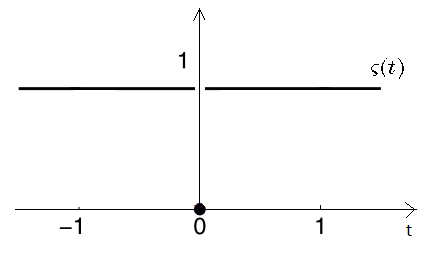

There are then many different approximate step functions that can be minimised. The figure below illustrates the many different approximate step functions that can be chosen to be minimised instead of an explicit step function.

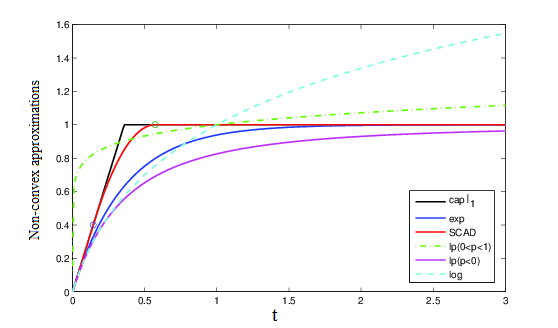

Depending on the application, and the biochemical network, one or other approximation may outperform the rest, therefore a pragmatic strategy is to try each and select the most sparse flux vector. The step set of function approximations [4] available are

 * 'cappedL1' : Capped-L1 norm

 * 'exp'      : Exponential function

 * 'log'      : Logarithmic function

 * 'SCAD'     : SCAD function

 * 'lp-'      : L_p norm with p<0

 * 'lp+'      : L_p norm with 0<p<1

Here we prepare a cell array of strings which indicate the set of step function approximations we wish to compare.

approximations = {'cappedL1','exp','log','SCAD','lp-','lp+'};

## Run the sparse linear optimisation solver

First we must build a problem structure to pass to the sparse solver, by adding an additional constraint requiring that the sparse flux solution also statisfy the optimal objective value from flux balance analysis

constraint.A = [S ; c'];
constraint.b = [b ; c'*vFBA];
constraint.csense = [csense;'E'];
constraint.lb = lb;
constraint.ub = ub;

Now we call the sparse linear step function approximations  

bestResult = n;
bestAprox = '';
for i=1:length(approximations)
    solution = sparseLP(char(approximations(i)),constraint);
    if solution.stat == 1
        nnzSol=nnz(abs(solution.x)>feasTol);
        fprintf('%u%s%s',nnzSol,' active reactions in the sparseFBA solution with ', char(approximations(i)));
        if bestResult > nnzSol
            bestResult=nnzSol;
            bestAprox = char(approximations(i));
            solutionL0 = solution;
        end
    end
end

247 active reactions in the sparseFBA solution with cappedL1

247 active reactions in the sparseFBA solution with exp

247 active reactions in the sparseFBA solution with log

247 active reactions in the sparseFBA solution with SCAD

247 active reactions in the sparseFBA solution with lp-

247 active reactions in the sparseFBA solution with lp+

Select the most sparse flux vector, unless there is a numerical problem.

if ~isequal(bestAprox,'')
    vBest = solutionL0.x;
else
    vBest = [];
    error('Min L0 problem error !!!!')
end

Report the best approximation

display(strcat('Best step function approximation: ',bestAprox));

Best step function approximation:cappedL1


Report the number of active reactions in the most sparse flux vector

fprintf('%u%s',nnz(abs(vBest)>feasTol),' active reactions in the best sparse flux balance analysis solution.');

247 active reactions in the best sparse flux balance analysis solution.

Warn if there might be a numerical issue with the solution

feasError=norm(constraint.A * solutionL0.x - constraint.b,2);
if feasError>feasTol
    fprintf('%g\t%s\n',feasError, ' feasibily error.')
    warning('Numerical issue with the sparseLP solution')
end

## Heuristically check if the selected set of reactions is minimal

Each step function approximation minimises a different problem than minimising the zero norm explicitly. Therefore it is wise to test, at least heuristically, if the most sparse approximate solution to minimising the zero norm is at least locally optimal, in the sense that the set of preicted reactions cannot be reduced by omitting, one by one, an active reaction. If it is locally optimal in this sense, one can be more confident that the  most sparse approximate solution is the most sparse solution, but still there is no global guarantee, as it is a combinatorial issue.

Identify the set of predicted active reactions

activeRxnBool = abs(vBest)>feasTol;
nActiveRnxs = nnz(activeRxnBool);
activeRxns = false(n,1);
activeRxns(activeRxnBool) = true;
minimalActiveRxns=activeRxns;


Close all predicted non-active reactions by setting their lb = ub = 0

lbSub = model.lb;
ubSub = model.ub;
lbSub(~activeRxns) = 0;
lbSub(~activeRxns) = 0;

Generate an LP problem  to be reduced

% Check if one still can achieve the same objective
LPproblem = struct('c',-c,'osense',-1,'A',S,'csense',csense,'b',b,'lb',lbSub,'ub',ubSub);

For each active reaction in the most sparse approximate flux vector, one by one, set the reaction bounds to zero, then test if the optimal flux balance analysis objective value is still attained. If it is, then that reaction is not part of the minimal set. If it is not, then it is probably part of the minimal set.

for i=1:n
    if activeRxnBool(i)
        LPproblem.lb = model.lb;
        LPproblem.ub = model.ub;
        %close bounds on this reaction
        LPproblem.lb(i) = 0;% Close the reaction
        LPproblem.ub(i) = 0;% Close the reaction
        %solve the LP problem
        LPsolution = solveCobraLP(LPproblem);
        %check if the optimal FBA objective is attained
        if LPsolution.stat == 1 && abs(LPsolution.obj + c'*vFBA)<1e-8
            minimalActiveRxns(i) = 0;
            vBestTested = LPsolution.full(1:n);
        else
            %relax those bounds if reaction appears to be part of the minimal set
            LPproblem.lb(i) = model.lb(i);
            LPproblem.ub(i) = model.ub(i);
        end
    end
end

Report the number of active reactions in the approximately most sparse flux vector, or the reduced approximately most sparse flux vector, if it is more sparse.

if nnz(minimalActiveRxns)<nnz(activeRxns)
    fprintf('%u%s',nnz(abs(vBestTested)>feasTol),' active reactions in the best sparseFBA solution (tested).');
    nonZeroFlag = 1;
    printFluxVector(model, vBestTested, nonZeroFlag);
else
    fprintf('%u%s',nnz(abs(vBest)>feasTol),' active reactions in the best sparseFBA solution (tested).');
end

247 active reactions in the best sparseFBA solution (tested).

## REFERENCES

[1] Meléndez-Hevia, E., Isidoro, A. (1085). The game of the pentose phosphate cycle. Journal of Theoretical Biology 117, 251-263.

[2] Thiele, I., Swainston, N., Fleming, R.M., Hoppe, A., Sahoo, S., Aurich, M.K., Haraldsdottir, H., Mo, M.L., Rolfsson, O., Stobbe, M.D., et al. (2013). A community-driven global reconstruction of human metabolism. Nat Biotechnol 31, 419-425.

[3] Fleming, R.M.T., et al. (*submitted*, 2017). Cardinality optimisation in constraint-based modelling: illustration with Recon 3D.

[4] Le Thi, H.A., Pham Dinh, T., Le, H.M., and Vo, X.T. (2015). DC approximation approaches for sparse optimization. European Journal of Operational Research 244, 26-46.